# Position, Velocity, Acceleration, and Jerk

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code generates the plot of jerk vs time.

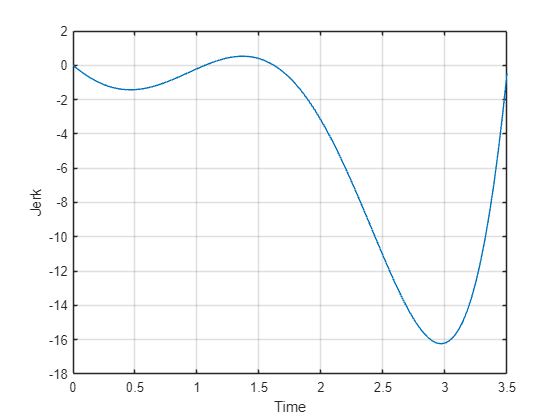

t = linspace(0, 3.5);
j = t.^5 - 5.2*t.^4 + 5*t.^3 + 5*t.^2 - 6*t;
plot(t, j)
grid on
ylabel("Jerk")
xlabel("Time")

## Task 1

The jerk of a car has been plotted in the script to the right. To find the position of this car we need to solve a third-order ODE, or the equivalent set of three first-order ODEs:

*d**y/d**t*=*v*

*d**v/d**t*=*a*

*d**a/d**t*=*j*(*t*)

These equations have already been incorporated into the ODE function `motionFunc` at the bottom of the script. 

tRange = [0 3.5];
Y0 = [0; 15; 0];
[tSol, YSol] = ode45(@motionFunc, tRange, Y0);

## Task 2

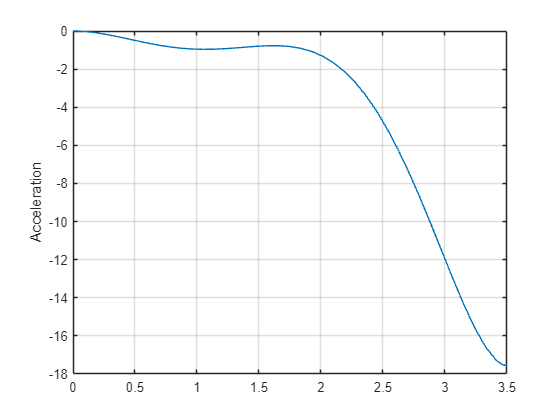

a = YSol(:, 3);
plot(tSol, a)
grid on
ylabel("Acceleration")

## Task 3

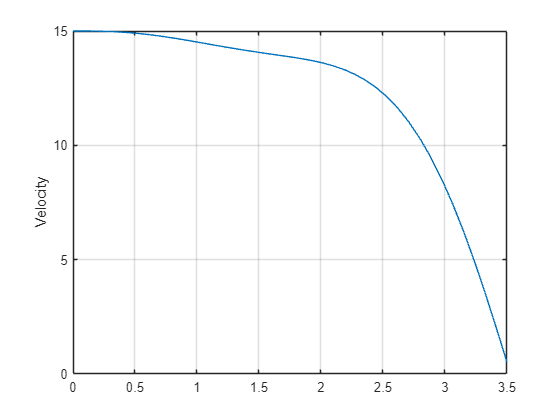

v = YSol(:, 2);
plot(tSol, v)
grid on
ylabel("Velocity")

## Task 4

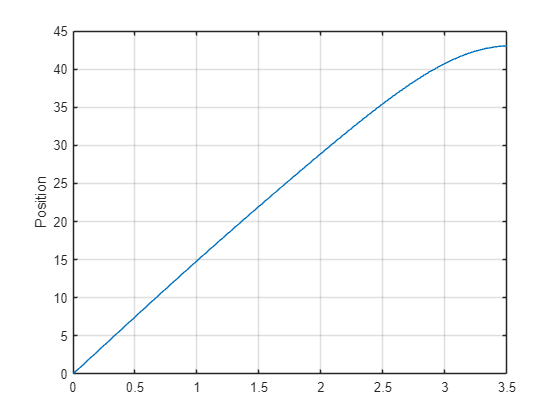

y = YSol(:, 1);
plot(tSol, y)
grid on
ylabel("Position")

## ODE Function

Do not edit. This code defines the ODE function for the system of ODEs.

function dYdt = motionFunc(t, Y)
    % Extract v and a from the second and third elements of vector Y
    v = Y(2);
    a = Y(3);
    
    % Calculate da/dat
    dadt = t.^5 - 5.2*t.^4 + 5*t.^3 + 5*t.^2 - 6*t;
    
    % Calculate dv/dt
    dvdt = a;
    
    % Calculate dy/dt
    dydt = v;
    
    %Store derivatives to output vector
    dYdt = [dydt; dvdt; dadt];
end